## Testbench Data

%FR60

filename = '20250822_CYCLE-no-pause_15x10_i100_i150_FR60_gamry_data.csv';
data = readtable(filename);

data = data(9878 :109878,:);
t = seconds(data.t_abs - data.t_abs(1));
I = data.I_kl;
OCV = data.U_CH2;
ocp_neg = data.U_CH3;
ocp_pos = data.U_CH4;
q = (0.060/60)*ones(size(t));
T_cell = 303.15;

%FR75

filename = '20250811_CYCLE-no-pause_15x10_i100_i150_FR75_gamry_data.csv';
data = readtable(filename);

data = data(1:100000,:);
t = seconds(data.t_abs - data.t_abs(1));
I = data.I_kl;
OCV = data.U_CH2;
ocp_neg = data.U_CH3;
ocp_pos = data.U_CH4;
q = (0.075/60)*ones(size(t));
T_cell = 305.15;

## Parameters

N = numel(t);

% current with coulomb-efficiency
I  = data.I_kl;
eta_coul  = 0.98;
I_eff       = I;             % preallocate
idx_chg     =  I >= 0;       % charge 
idx_dch     =  I <  0;       % discharge
I_eff(idx_chg) =  eta_coul * I(idx_chg);
I_eff(idx_dch) = (1/eta_coul) * I(idx_dch);

%  MODEL PARAMETERS

R_u    = 8.314;          % J/(mol·K)
F      = 96485.33;       % C/mol

k2 = 1.30e-11;  k3 = 1.25e-11;
k4 = 3.81e-12;  k5 = 3.10e-12;
k_ox =  0;%3.1e-7;

n = 1;                    % number of cells
S_elec = 0.2 * 0.1;       % m²
d_mem  = 50e-6;           % m
d_e    = 0.0018;          % m
V_total = 3.0;            % L

v_c = d_e * S_elec * n * 1000;            % L
v_t = (V_total - 2*n*v_c)/2;              % L

% system matrices
A1 = [ -1/(n*v_c), 0, 0, 0,  1/(n*v_c), 0, 0, 0;
        0,-1/(n*v_c),0,0,   0, 1/(n*v_c),0,0;
        0,0,-1/(n*v_c),0,   0,0, 1/(n*v_c),0;
        0,0,0,-1/(n*v_c),   0,0,0, 1/(n*v_c);
        1/v_t,0,0,0, -1/v_t,0,0,0;
        0,1/v_t,0,0, 0,-1/v_t,0,0;
        0,0,1/v_t,0, 0,0,-1/v_t,0;
        0,0,0,1/v_t, 0,0,0,-1/v_t ];

A2 = [ -k2,0,-k4,-2*k5, 0,0,0,0;
        0,-k3,2*k4,3*k5, 0,0,0,0;
       3*k2,2*k3,-k4,0,  0,0,0,0;
      -2*k2,-k3,0,-k5,   0,0,0,0;
        0,0,0,0, -k_ox*d_mem*S_elec*(v_t/v_c),0,0,0;
        0,0,0,0, 0,-k_ox*d_mem*S_elec*(v_t/v_c),0,0;
        0,0,0,0, 0,0,0,0;
        0,0,0,0, 0,0,0,0 ];

b = [1;-1;-1;1;0;0;0;0];
B_const = b / (F * v_c);

## Forward Euler simulation

X = zeros(8,N);
x = [0.18 1.42 1.42 0.18 0.18 1.42 1.42 0.18]';
X(:,1) = x;

for k = 1:N-1
    dt = t(k+1) - t(k);                         
    A_k = q(k)*A1 + (S_elec/d_mem/v_c)*A2;
    x   = x + dt * ( A_k * x + B_const * I_eff(k) );
    X(:,k+1) = x;
end

## UKF

tic;
% UKF Parameter
alpha  = 1e-3;
beta   = 2;
kappa  = 0;
Q      = 1e-9 * eye(8);     % process-noise cov
R      = 1e-2 * eye(2);     % measurement-noise cov
L = 8;
lambda = alpha^2 * (L+kappa) - L;

% Sigma point weights
wm0 = lambda/(L+lambda)

wm0 = -1.0000e+06

wc0 = wm0 + (1 - alpha^2 + beta)

wc0 = -1.0000e+06

wm = [wm0, repmat(1/(2*(L+lambda)),1,2*L)]; % gamma = sqrt(L+lamda)
wc = [wc0, repmat(1/(2*(L+lambda)),1,2*L)]

wc = 1.0e+05 *

  -10.0000    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250



% initial estimate & covariance
% x_hat = 0.8 * ones(L,1);
x_hat = [1.5, 0.1,0.6 ,1.0,1.1,0.5,0.9,0.7]';
% P     = 1e-4 * eye(L);
P     = 1e-2 * eye(L);

X_ukf = zeros(L,N);
X_ukf(:,1) = x_hat;

% state and measured functions
stateFcn = @(x,u,dt) x + dt * (u.A_k * x + u.B * u.I);  % Euler step
 % measFcn  = @(x) [ x(5)/max(x(6),eps) ;
                  % x(8)/max(x(7),eps) ];
measFcn  = @(x) [x(5)/x(6) ;
                 x(8)/x(7) ];
% Helper function (
function [m,P] = unscentedTransform(chi,Wm,Wc,R)
    m  = chi * Wm.';                     % weighted mean 
    Xc = chi - m;                        % centred sigma points
    P  = Xc * diag(Wc) * Xc.' + R;       % covariance + noise
end

for k = 1:N-1
    dt_k = t(k+1) - t(k);          

    % input struct
    u_k.A_k = q(k) * A1 + (S_elec/d_mem/v_c) * A2;
    u_k.B   = B_const;
    u_k.I   = I_eff(k);

    % 1) sigma-point generation                           % sqrt(L+lambda)  scaling factor
    S = chol(P,'lower');
    chi = [x_hat, x_hat + sqrt(L+lambda)*S, x_hat - sqrt(L+lambda)*S]; %(2L+1) sigma point

    % 2) prediction 
    chi_pred = zeros(size(chi));
    for ii = 1:2*L+1
        chi_pred(:,ii) = stateFcn(chi(:,ii), u_k, dt_k);
    end
    [x_pred, P_pred] = unscentedTransform(chi_pred, wm, wc, Q);

    % 3) measurement update 
    z_sigma = zeros(2, 2*L+1);
    for ii = 1:2*L+1
        z_sigma(:,ii) = measFcn(chi_pred(:,ii));
    end
    [z_pred, P_zz] = unscentedTransform(z_sigma, wm, wc, R);

    Xc   = chi_pred - x_pred;
    Zc   = z_sigma  - z_pred;
    P_xz = Xc * diag(wc) * Zc';
    %P_xz = Xc  * Zc';

    K  = P_xz / P_zz;                          % kalman gain
    z_k = [ X(5,k)/X(6,k) ; X(8,k)/X(7,k) ];   

    x_hat = x_pred + K * (z_k - z_pred);
    P     = P_pred - K * P_zz * K';

    X_ukf(:,k+1) = x_hat;                      %state update
end
t_lyap = toc;   % stop the stopwatch
fprintf('Lyapunov observer runtime = %.3f seconds\n', t_lyap);

Lyapunov observer runtime = 2.211 seconds


err = X - X_ukf;                % absolute error
rmse = sqrt(mean(err.^2, 2));   % 1x8, RMSE per state
rmse_anolyte_cell   = mean(rmse(1:2));
rmse_catholyte_cell = mean(rmse(3:4));
rmse_anolyte_tank   = mean(rmse(5:6));
rmse_catholyte_tank = mean(rmse(7:8));
% rmse_con_obs = sqrt(mean((X - X_ukf).^2,1));
% rmse_con_obs = sqrt(mean((X - X_estimated).^2));
rmse_con_obs = sqrt(mean((X - X_ukf).^2,2));


## Model vs esimated

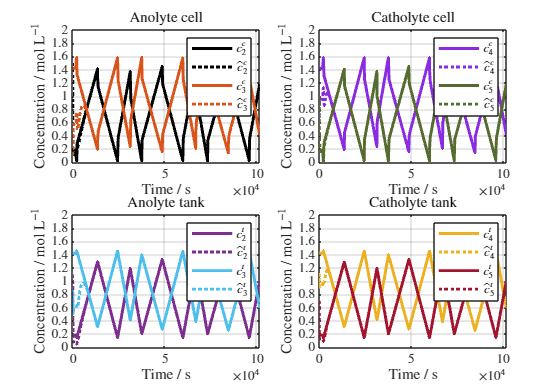

%% Compare MODEL (X) vs ESTIMATED (X_est) — grouped by compartments
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

% Dark, high-contrast colors (8 distinct)  <-- same palette you used
colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];

lw = 2.0;                    % thicker lines for thesis PDFs
ls_est = ':';               % estimated linestyle

% --- Anolyte cell: states 1 & 2
ax1 = subplot(2,2,1);
plot(t, X(1,:),     '-', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(t, X_ukf(1,:), ls_est, 'Color',colors(1,:), 'LineWidth',lw);
plot(t, X(2,:),     '-', 'Color',colors(2,:), 'LineWidth',lw);
plot(t, X_ukf(2,:), ls_est, 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Concentration / mol L$^{-1}$');
title('Anolyte cell');
grid on; legend({'$c^c_2$','$\hat{c}^c_2$','$c^c_3$','$\hat{c}^c_3$'},'Location','northeast');

% --- Catholyte cell: states 3 & 4
ax2 = subplot(2,2,2);
plot(t, X(3,:),     '-', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(t, X_ukf(3,:), ls_est, 'Color',colors(3,:), 'LineWidth',lw);
plot(t, X(4,:),     '-', 'Color',colors(4,:), 'LineWidth',lw);
plot(t, X_ukf(4,:), ls_est, 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Concentration / mol L$^{-1}$');
title('Catholyte cell');
grid on; legend({'$c^c_4$','$\hat{c}^c_4$','$c^c_5$','$\hat{c}^c_5$'},'Location','northeast');

% --- Anolyte tank: states 5 & 6
ax3 = subplot(2,2,3);
plot(t, X(5,:),     '-', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(t, X_ukf(5,:), ls_est, 'Color',colors(5,:), 'LineWidth',lw);
plot(t, X(6,:),     '-', 'Color',colors(6,:), 'LineWidth',lw);
plot(t, X_ukf(6,:), ls_est, 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Concentration / mol L$^{-1}$');
title('Anolyte tank');
grid on; legend({'$c^t_2$','$\hat{c}^t_2$','$c^t_3$','$\hat{c}^t_3$'},'Location','northeast');

% --- Catholyte tank: states 7 & 8
ax4 = subplot(2,2,4);
plot(t, X(7,:),     '-', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(t, X_ukf(7,:), ls_est, 'Color',colors(7,:), 'LineWidth',lw);
plot(t, X(8,:),     '-', 'Color',colors(8,:), 'LineWidth',lw);
plot(t, X_ukf(8,:), ls_est, 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Concentration / mol L$^{-1}$');
title('Catholyte tank');
grid on; legend({'$c^t_4$','$\hat{c}^t_4$','$c^t_5$','$\hat{c}^t_5$'},'Location','northeast');

% Make all subplots share the same y-axis and fix limits to [0, 1.6]
linkaxes([ax1, ax2, ax3, ax4], 'y');
ylim(ax1, [0 2]);  % propagates to others because of linkaxes

% (Optional) consistent y-ticks
set([ax1, ax2, ax3, ax4], 'YTick', 0:0.2:2);



% sgtitle(' Discrete Model vs. Estimated (UKF) Concentrations (Flowrate 75 mL/min)','FontSize',14);



% Save as vector PDF
exportgraphics(gcf, 'D_UKF_FR75.pdf', ...
    'ContentType','vector', 'BackgroundColor','white');

reltive_er = [abs(X- X_ukf)./abs(X)]/100;
rel = reltive_er';

## Relative error

%% ---------- Relative error (|X - X_ukf| / |X|) ----------
if size(X,1) ~= 8 && size(X,2) == 8,     X = X.';     end
if size(X_ukf,1) ~= 8 && size(X_ukf,2) == 8, X_ukf = X_ukf.'; end

t = t(:);                    % your time vector (same one you used above)
if numel(t) ~= size(X,2)     % if t is a row/time mismatch, try transpose
    t = t.';                 % (MATLAB will accept row or column for plot)
end

% Element-wise safe denominator to avoid NaN/Inf when X == 0
den = max(abs(X), 1e-12);
rel_err = abs(X - X_ukf) ./ den;     % 8 x N
rel_err_pct = 100 * rel_err;         % percentage

%% ---------- Plot relative error (grouped by compartments) ----------
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];
lw = 2.0;

% --- Anolyte cell: states 1 & 2
ax1 = subplot(2,2,1);
plot(t, rel_err_pct(1,:), '-', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(t, rel_err_pct(2,:), '-', 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte cell'); grid on
legend({'$e_r(C^c_1)$','$e_r(C^c_2)$'},'Location','northeast');

% --- Catholyte cell: states 3 & 4
ax2 = subplot(2,2,2);
plot(t, rel_err_pct(3,:), '-', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(t, rel_err_pct(4,:), '-', 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte cell'); grid on
legend({'$e_r(C^c_3)$','$e_r(C^c_4)$'},'Location','northeast');

% --- Anolyte tank: states 5 & 6
ax3 = subplot(2,2,3);
plot(t, rel_err_pct(5,:), '-', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(t, rel_err_pct(6,:), '-', 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte tank'); grid on
legend({'$e_r(C^t_5)$','$e_r(C^t_6)$'},'Location','northeast');

% --- Catholyte tank: states 7 & 8
ax4 = subplot(2,2,4);
plot(t, rel_err_pct(7,:), '-', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(t, rel_err_pct(8,:), '-', 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte tank'); grid on
legend({'$e_r(C^t_7)$','$e_r(C^t_8)$'},'Location','northeast');

sgtitle('Relative Error between Model and UKF Estimates','FontSize',14);
% 
% % (Optional) unify x-ticks like 0,4,6,8,10,12 ×10^4
% axs = [ax1,ax2,ax3,ax4];
% set(axs,'XLim',[0 1.2e5],'XTick',[0 2e4 4e4 6e4 8e4 10e4 12e4]);
% for ax = axs, ax.XAxis.Exponent = 4; end
% linkaxes(axs,'x');


## Relative error

%% Relative Error Plots (Model vs UKF/Observer)
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

% Colors (same as before)
colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];

lw = 2.0;  % thicker lines
time = t(:);

% rel_err_pct = 100*((X-X_est)./X)';
rel_err_pct = 100*(abs(X-X_ukf)./(abs(X)+1))';

% --- Compute relative error safely (%)
% den = max((X), 1e-12);              % safe denominator
% rel_err_pct = (100*(X - X_est) ./ den)';

% --- Anolyte cell: states 1 & 2
ax1 = subplot(2,2,1);
plot(time, rel_err_pct(:,1), '-.', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,2), '-.', 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte cell'); grid on;
legend({'$e_r(C^c_2)$','$e_r(C^c_3)$'},'Location','northeast');


% --- Catholyte cell: states 3 & 4
ax2 = subplot(2,2,2);
plot(time, rel_err_pct(:,3), '-.', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,4), '-.', 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte cell'); grid on;
legend({'$e_r(C^c_4)$','$e_r(C^c_5)$'},'Location','northeast');

% --- Anolyte tank: states 5 & 6
ax3 = subplot(2,2,3);
plot(time, rel_err_pct(:,5), '-.', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,6), '-.', 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte tank'); grid on;
legend({'$e_r(C^t_2)$','$e_r(C^t_3)$'},'Location','northeast');

% --- Catholyte tank: states 7 & 8
ax4 = subplot(2,2,4);
plot(time, rel_err_pct(:,7), '-.', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,8), '-.', 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte tank'); grid on;
legend({'$e_r(C^t_4)$','$e_r(C^t_5)$'},'Location','northeast');

sgtitle('Relative Error between Discrete Model and Observer (Flowrate 75 mL/min)','FontSize',14);

% --- Optional: unify x-axis ticks
axs = [ax1,ax2,ax3,ax4];
% set(axs,'YLim',[-10 80]);   % common y-axis limits
set(axs,'YLim',[0 80],'YTick',[0 10 20 30 40 50 60 70 80]);


set(axs,'XLim',[0 1.2e5],'XTick',[0 2e4 4e4 6e4 8e4 10e4 12e4]);

% Save as vector PDF
exportgraphics(gcf, 'Error_DisModel_vs_Observer_FR75.pdf', ...
    'ContentType','vector', 'BackgroundColor','white');

% %% Relative Error Plots (Model vs UKF/Observer) with Insets
% set(groot,'defaultAxesTickLabelInterpreter','latex'); 
% set(groot,'defaultLegendInterpreter','latex');
% set(groot,'defaultTextInterpreter','latex');
% 
% figure('Position',[100 100 1000 700]);
% 
% % Colors (same as before)
% colors = [
%     0.00 0.00 0.00;   % black
%     0.85 0.33 0.10;   % dark orange
%     0.541 0.169 0.886;% BlueViolet
%     0.333 0.420 0.184;% dark olive green
%     0.49  0.18  0.56; % purple
%     0.30  0.75  0.93; % cyan
%     0.93  0.69  0.13; % gold
%     0.64  0.08  0.18  % dark red
% ];
% 
% lw = 2.0;  
% time = t(:);
% 
% % Relative error calculation (safe)
% rel_err_pct = 100*(abs(X - X_ukf) ./ (abs(X) + 1))';  % N×8
% 
% %% --- Anolyte cell: states 1 & 2
% ax1 = subplot(2,2,1);
% plot(time, rel_err_pct(:,1), '-.', 'Color',colors(1,:), 'LineWidth',lw); hold on
% plot(time, rel_err_pct(:,2), '-.', 'Color',colors(2,:), 'LineWidth',lw);
% xlabel('Time / s'); ylabel('Relative error / \%');
% title('Anolyte cell'); grid on;
% legend({'$e_r(C^c_2)$','$e_r(C^c_3)$'},'Location','northeast');
% makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:));
% 
% %% --- Catholyte cell: states 3 & 4
% ax2 = subplot(2,2,2);
% plot(time, rel_err_pct(:,3), '-.', 'Color',colors(3,:), 'LineWidth',lw); hold on
% plot(time, rel_err_pct(:,4), '-.', 'Color',colors(4,:), 'LineWidth',lw);
% xlabel('Time / s'); ylabel('Relative error / \%');
% title('Catholyte cell'); grid on;
% legend({'$e_r(C^c_4)$','$e_r(C^c_5)$'},'Location','northeast');
% makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:));
% 
% %% --- Anolyte tank: states 5 & 6
% ax3 = subplot(2,2,3);
% plot(time, rel_err_pct(:,5), '-.', 'Color',colors(5,:), 'LineWidth',lw); hold on
% plot(time, rel_err_pct(:,6), '-.', 'Color',colors(6,:), 'LineWidth',lw);
% xlabel('Time / s'); ylabel('Relative error / \%');
% title('Anolyte tank'); grid on;
% legend({'$e_r(C^t_2)$','$e_r(C^t_3)$'},'Location','northeast');
% makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:));
% 
% %% --- Catholyte tank: states 7 & 8
% ax4 = subplot(2,2,4);
% plot(time, rel_err_pct(:,7), '-.', 'Color',colors(7,:), 'LineWidth',lw); hold on
% plot(time, rel_err_pct(:,8), '-.', 'Color',colors(8,:), 'LineWidth',lw);
% xlabel('Time / s'); ylabel('Relative error / \%');
% title('Catholyte tank'); grid on;
% legend({'$e_r(C^t_4)$','$e_r(C^t_5)$'},'Location','northeast');
% makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:));
% 
% sgtitle('Relative Error between Discrete Model and Observer (Flowrate 75 mL/min)','FontSize',14);
% 
% % --- unify main plots
% axs = [ax1,ax2,ax3,ax4];
% set(axs,'YLim',[0 80],'YTick',0:10:80);
% set(axs,'XLim',[0 1.2e5],'XTick',0:2e4:1.2e5);
% 
% %% --- Helper function for inset zoom
% function makeInset(parentAx,time,y1,y2,c1,c2)
%     % Create inset axes inside parent subplot
%     pos = get(parentAx,'Position');
%     insetPos = [pos(1)+0.55*pos(3) , pos(2)+0.55*pos(4) , 0.3*pos(3) , 0.3*pos(4)];
%     axInset = axes('Position',insetPos);
%     plot(axInset,time,y1,'-.','Color',c1,'LineWidth',1.5); hold on
%     plot(axInset,time,y2,'-.','Color',c2,'LineWidth',1.5);
%     set(axInset,'XLim',[0 2e4],'YLim',[0 20],'FontSize',8,'Box','on');
%     grid(axInset,'on');
% end

%% Relative Error Plots (Model vs UKF/Observer) with TWO Insets
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

% Colors (same as before)
colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];

lw = 2.0;  
time = t(:);

% Relative error calculation (safe)
% rel_err_pct = 100*(abs(X - X_ukf) ./ (abs(X) + 1))';  % N×8
rel_err_pct = 100*(abs(X_ukf-X) ./ (abs(X) + 1))';  % N×8

%% --- Anolyte cell: states 1 & 2
ax1 = subplot(2,2,1);
plot(time, rel_err_pct(:,1), '-.', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,2), '-.', 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte cell'); grid on;
legend({'$e(c^c_2)$','$e(c^c_3)$'},'Location','northeast');
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),[0 2e4 0 20]);
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),[4e4 6e4 0 5]);

%% --- Catholyte cell: states 3 & 4
ax2 = subplot(2,2,2);
plot(time, rel_err_pct(:,3), '-.', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,4), '-.', 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte cell'); grid on;
legend({'$e(c^c_4)$','$e(c^c_5)$'},'Location','northeast');
makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),[0 2e4 0 20]);
makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),[4e4 6e4 0 5]);

%% --- Anolyte tank: states 5 & 6
ax3 = subplot(2,2,3);
plot(time, rel_err_pct(:,5), '-.', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,6), '-.', 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Anolyte tank'); grid on;
legend({'$e(c^t_2)$','$e(c^t_3)$'},'Location','northeast');
makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),[0 2e4 0 20]);
makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),[4e4 6e4 0 5]);

%% --- Catholyte tank: states 7 & 8
ax4 = subplot(2,2,4);
plot(time, rel_err_pct(:,7), '-.', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,8), '-.', 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%');
title('Catholyte tank'); grid on;
legend({'$e(c^t_4)$','$e(c^t_5)$'},'Location','northeast');
makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),[0 2e4 0 20]);
makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),[4e4 6e4 0 5]);

sgtitle('Relative Error between Discrete Model and Observer (Flowrate 75 mL/min)','FontSize',14);

% --- unify main plots
axs = [ax1,ax2,ax3,ax4];
set(axs,'YLim',[0 80],'YTick',0:10:80);
set(axs,'XLim',[0 1.2e5],'XTick',0:2e4:1.2e5);

%% --- Helper function for inset zoom
% function makeInset(parentAx,time,y1,y2,c1,c2,lim)
%     % lim = [xmin xmax ymin ymax]
%     pos = get(parentAx,'Position');
%     insetPos = [pos(1)+0.55*pos(3) , pos(2)+0.55*pos(4) , 0.3*pos(3) , 0.3*pos(4)];
%     axInset = axes('Position',insetPos);
%     plot(axInset,time,y1,'-.','Color',c1,'LineWidth',1.5); hold on
%     plot(axInset,time,y2,'-.','Color',c2,'LineWidth',1.5);
%     set(axInset,'XLim',lim(1:2),'YLim',lim(3:4),'FontSize',8,'Box','on');
%     grid(axInset,'on');
% end

%% Relative Error Plots (Model vs UKF/Observer) with TWO Insets per subplot
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

% Colors (same as before)
colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];

lw   = 2.0;  
time = t(:);                % N×1

% ---------- relative error formula ----------
rel_err_pct = 100 * (abs(X - X_ukf) ./ (abs(X) + 1))';   % N×8

% ---------- Main plots ----------
ax1 = subplot(2,2,1);
plot(time, rel_err_pct(:,1), '-.', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,2), '-.', 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Anolyte cell'); grid on;
legend({'$e(c^c_1)$','$e(c^c_2)$'},'Location','northeast');

ax2 = subplot(2,2,2);
plot(time, rel_err_pct(:,3), '-.', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,4), '-.', 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Catholyte cell'); grid on;
legend({'$e(c^c_3)$','$e(c^c_4)$'},'Location','northeast');

ax3 = subplot(2,2,3);
plot(time, rel_err_pct(:,5), '-.', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,6), '-.', 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Anolyte tank'); grid on;
legend({'$e(c^t_5)$','$e(c^t_6)$'},'Location','northeast');

ax4 = subplot(2,2,4);
plot(time, rel_err_pct(:,7), '-.', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,8), '-.', 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Catholyte tank'); grid on;
legend({'$e(c^t_7)$','$e(c^t_8)$'},'Location','northeast');

sgtitle('Relative Error between Discrete Model and Observer (Flowrate 75 mL/min)','FontSize',14);

% Unify main axes limits/ticks
axs = [ax1,ax2,ax3,ax4];
set(axs,'YLim',[0 80],'YTick',0:10:80);
set(axs,'XLim',[0 1.2e5],'XTick',0:2e4:1.2e5);

% ---------- Insets (two per subplot) ----------
% Inset ranges
limA = [0, 2e4, 0, 20];     % [xmin xmax ymin ymax]
limB = [4e4, 6e4, 0, 0.25];

% Positions (relative to parent subplot)
posA = [0.58 0.58 0.37 0.35];  % top-right
posB = [0.58 0.12 0.37 0.35];  % bottom-right

% Add to all subplots
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),limA,posA);
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),limB,posB);

makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),limA,posA);
makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),limB,posB);

makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),limA,posA);
makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),limB,posB);

makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),limA,posA);
makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),limB,posB);

%% -------- Helper function for insets --------
% function makeInset(parentAx,time,y1,y2,c1,c2,lim,posRel)
%     % lim    = [xmin xmax ymin ymax]
%     % posRel = [x y w h] relative to parent subplot (0–1)
%     oldUnits = get(parentAx,'Units');
%     set(parentAx,'Units','normalized');
%     parentPos = get(parentAx,'Position');
% 
%     insetPos = [ ...
%         parentPos(1) + posRel(1)*parentPos(3), ...
%         parentPos(2) + posRel(2)*parentPos(4), ...
%         posRel(3)*parentPos(3), ...
%         posRel(4)*parentPos(4)];
% 
%     axInset = axes('Position', insetPos);
%     plot(axInset,time,y1,'-.','Color',c1,'LineWidth',1.3); hold(axInset,'on');
%     plot(axInset,time,y2,'-.','Color',c2,'LineWidth',1.3);
%     set(axInset,'XLim',lim(1:2),'YLim',lim(3:4),'FontSize',8,'Box','on');
%     grid(axInset,'on');
% 
%     set(parentAx,'Units',oldUnits);
% end

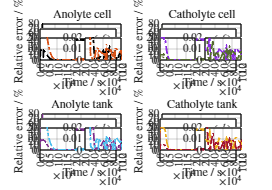

%% Relative Error Plots (Model vs UKF/Observer) with TWO Insets per subplot
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');

figure('Position',[100 100 1000 700]);

% Colors (same as before)
colors = [
    0.00 0.00 0.00;   % black
    0.85 0.33 0.10;   % dark orange
    0.541 0.169 0.886;% BlueViolet
    0.333 0.420 0.184;% dark olive green
    0.49  0.18  0.56; % purple
    0.30  0.75  0.93; % cyan
    0.93  0.69  0.13; % gold
    0.64  0.08  0.18  % dark red
];

lw   = 2.0;  
time = t(:);                % N×1

% Your relative error formula
rel_err_pct = 100 * (abs(X - X_ukf) ./ (abs(X) + 1))';   % N×8
% rel_err_pct = 100 * (abs(X_ukf - X) ./ (abs(X)))';   % RE

% ---------- Main plots ----------
ax1 = subplot(2,2,1);
plot(time, rel_err_pct(:,1), '-.', 'Color',colors(1,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,2), '-.', 'Color',colors(2,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Anolyte cell'); grid on;
lg = legend({'$e(c^c_2)$','$e(c^c_3)$'},'Location','northeast'); set(lg,'FontSize',9);

ax2 = subplot(2,2,2);
plot(time, rel_err_pct(:,3), '-.', 'Color',colors(3,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,4), '-.', 'Color',colors(4,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Catholyte cell'); grid on;
lg = legend({'$e(c^c_4)$','$e(c^c_5)$'},'Location','northeast'); set(lg,'FontSize',9);

ax3 = subplot(2,2,3);
plot(time, rel_err_pct(:,5), '-.', 'Color',colors(5,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,6), '-.', 'Color',colors(6,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Anolyte tank'); grid on;
lg = legend({'$e(c^t_2)$','$e(c^t_3)$'},'Location','northeast'); set(lg,'FontSize',9);

ax4 = subplot(2,2,4);
plot(time, rel_err_pct(:,7), '-.', 'Color',colors(7,:), 'LineWidth',lw); hold on
plot(time, rel_err_pct(:,8), '-.', 'Color',colors(8,:), 'LineWidth',lw);
xlabel('Time / s'); ylabel('Relative error / \%'); title('Catholyte tank'); grid on;
lg = legend({'$e(c^t_4)$','$e(c^t_5)$'},'Location','northeast'); set(lg,'FontSize',9);

% sgtitle('Relative Error between Discrete Model and UKF (Flowrate 60 mL/min)','FontSize',14);

% Unify main axes limits/ticks
axs = [ax1,ax2,ax3,ax4];
set(axs,'YLim',[0 80],'YTick',0:10:80);
set(axs,'XLim',[0 1.2e5],'XTick',0:2e4:1.2e5);

% ---------- Insets (two per subplot, top-left & top-right) ----------
% Ranges
limA = [0,    2e4, 0, 20];  % [xmin xmax ymin ymax] startup
limB = [2e4, 10e4, 0,  0.02];   % mid-cycle

% Positions relative to parent subplot: [x y w h] (0..1)
posTopLeft  =[0.05 0.30 0.40 0.35];  % top-left inset
posTopRight = [0.55 0.30 0.40 0.35];  % top-right inset

% Add to all subplots
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),limA,posTopLeft);
makeInset(ax1,time,rel_err_pct(:,1),rel_err_pct(:,2),colors(1,:),colors(2,:),limB,posTopRight);

makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),limA,posTopLeft);
makeInset(ax2,time,rel_err_pct(:,3),rel_err_pct(:,4),colors(3,:),colors(4,:),limB,posTopRight);

makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),limA,posTopLeft);
makeInset(ax3,time,rel_err_pct(:,5),rel_err_pct(:,6),colors(5,:),colors(6,:),limB,posTopRight);

makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),limA,posTopLeft);
makeInset(ax4,time,rel_err_pct(:,7),rel_err_pct(:,8),colors(7,:),colors(8,:),limB,posTopRight);

%% -------- Helper function for insets --------
function makeInset(parentAx,time,y1,y2,c1,c2,lim,posRel)
    % lim    = [xmin xmax ymin ymax]
    % posRel = [x y w h] relative to parent subplot (0–1)
    oldUnits = get(parentAx,'Units');
    set(parentAx,'Units','normalized');
    parentPos = get(parentAx,'Position');

    insetPos = [ ...
        parentPos(1) + posRel(1)*parentPos(3), ...
        parentPos(2) + posRel(2)*parentPos(4), ...
        posRel(3)*parentPos(3), ...
        posRel(4)*parentPos(4)];

    axInset = axes('Position', insetPos);
    plot(axInset,time,y1,'-.','Color',c1,'LineWidth',1.3); hold(axInset,'on');
    plot(axInset,time,y2,'-.','Color',c2,'LineWidth',1.3);
    set(axInset,'XLim',lim(1:2),'YLim',lim(3:4),'FontSize',8,'Box','on');
    grid(axInset,'on');

    % ---- Custom ticks for each inset ----
    if lim(2) <= 2e4   % first inset (0–2e4)
        axInset.XTick = 0:0.5e4:2e4;         % 0, 0.5e4, 1e4, 1.5e4, 2e4
    elseif lim(2) == 1e5   % second inset (2e4–1e5) in your code
        axInset.XTick = 2e4:2e4:1e5;        % 2e4, 4e4, 6e4, 8e4, 1e5
    end

    % Format ticks as multiples of 10^4
    axInset.XAxis.Exponent = 4;
    axInset.XAxis.TickLabelFormat = '%.1f';   % show 0.5, 1.0, 1.5, 2.0 etc.

    set(parentAx,'Units',oldUnits);
end

% Save as vector PDF
exportgraphics(gcf, 'E_Dis_UKF_FR75.pdf', ...
    'ContentType','vector', 'BackgroundColor','white');

Arrays have incompatible sizes for this operation.

Related documentation